clc;   clear;   close all ;
f = [];
load('QandRnotEye_sineDisturbance.mat')		
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

## Load data


close all ;

ym1 = data{397}.Values.Data(:,1);
ym2 = data{397}.Values.Data(:,2);

y1 = data{365}.Values.Data(:,1);
y2 = data{365}.Values.Data(:,2);

disturbance = data{397}.Values.Data(:);

N = length(ym1);
final = 50000;
step = final/N;

t_sec = 0 : step : final-step;
t_hour = t_sec/3600;

## Plot output 1 - T_air

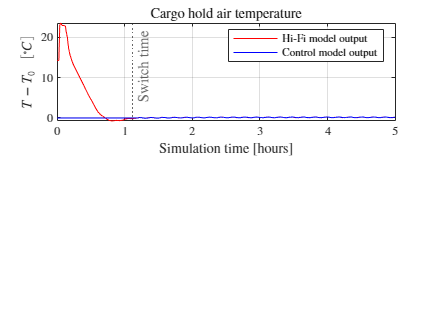

fig = myfig(-1);
f = [f fig];
subplot(2,1,1)
plot(t_hour,ym1,'r')
hold on
plot(t_hour,y1,'b')
hold off

title("Cargo hold air temperature")

grid on

xline(4000/3600,':','Switch time')
xlabel('Simulation time [hours]')
ylabel('$T-T_0 \:\:\:\: [^{\circ}C]$')
legend("Hi-Fi model output", "Control model output")

xlim([0 5])

## Plot output 2 - Superheat

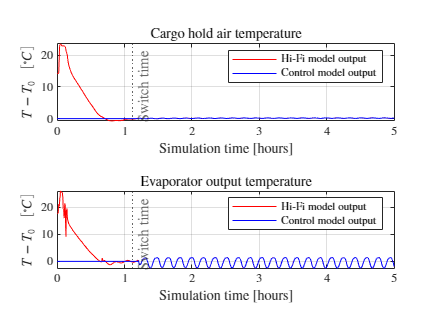


subplot(2,1,2)
plot(t_hour,ym2,'r')
hold on
plot(t_hour,y2,'b')
hold off


title({'';'Evaporator output temperature'})

grid on

xline(4000/3600,':','Switch time')
xlabel('Simulation time [hours]')
ylabel('$T-T_0 \:\:\:\: [^{\circ}C]$')
legend("Hi-Fi model output", "Control model output")

xlim([0 5])

## Plot output 1 - T_air zoom

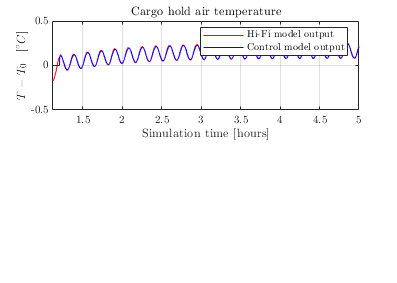

fig = myfig(-1);
f = [f fig];
subplot(2,1,1)
plot(t_hour,ym1,'r')
hold on
plot(t_hour,y1,'b')
hold off

title("Cargo hold air temperature")

grid on

% xline(4000/3600,':','Switch time')
xlabel('Simulation time [hours]')
ylabel('$T-T_0 \:\:\:\: [^{\circ}C]$')
legend("Hi-Fi model output", "Control model output")
ylim([-0.5 0.5])
xlim([4000/3600 5])

## Plot output 2 - Superheat zoom

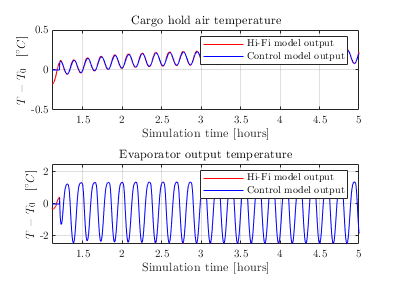


subplot(2,1,2)
plot(t_hour,ym2,'r')
hold on
plot(t_hour,y2,'b')
hold off


title({'';'Evaporator output temperature'})

grid on

% xline(4000/3600,':','Switch time')
xlabel('Simulation time [hours]')
ylabel('$T-T_0 \:\:\:\: [^{\circ}C]$')
legend("Hi-Fi model output", "Control model output")
ylim([-2.5 2.5])
xlim([4000/3600 5])

## Export

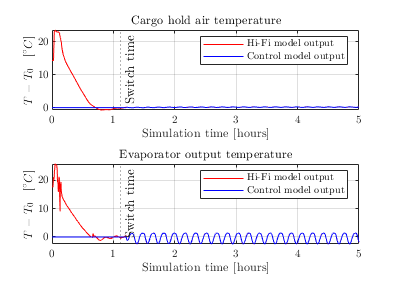


savepath = 'C:\Users\rasmu\Documents\Repositories\CA8_Writings\Graphics';
filenames = ["fig_LQR_wellTuned_sineDist.png", "fig_LQR_wellTuned_sineDist_zoom.png"];
myfigexport(savepath, f, filenames, "false", 'Figures', 300);